# PCA in MATLAB

% Dataset

data = load('face.mat');
X = data.X.';  %X : (N=520, dim=2576)
y = data.l.';  %y : (N=520, 1)

% Train/Test split - 8/2 for each ID

hpartition = cvpartition(y,"HoldOut",0.2,"Stratify",true);
idxTrain = training(hpartition); idxTest = test(hpartition);
X_train = X(idxTrain,:); y_train = y(idxTrain,:);
X_test = X(idxTest,:); y_test = y(idxTest,:);

% (p2) 4-batches of training set - 4 same-sized batches

%8*a+b -> 1~416(52) -> a:0~51
idx = [1:8]; tmp = ([0:51]*8).'; idx = repmat(idx,52,1) + tmp;
idx_1 = reshape(idx(:,1:2).',1,[]).'; idx_2 = reshape(idx(:,3:4).',1,[]).';
idx_3 = reshape(idx(:,5:6).',1,[]).'; idx_4 = reshape(idx(:,7:8).',1,[]).';

%Subsets
X_train_1 = X_train(idx_1,:); y_train_1 = y_train(idx_1,:);
X_train_2 = X_train(idx_2,:); y_train_2 = y_train(idx_2,:);
X_train_3 = X_train(idx_3,:); y_train_3 = y_train(idx_3,:);
X_train_4 = X_train(idx_4,:); y_train_4 = y_train(idx_4,:);

# PCA : Whole batch

% Performing PCA - all eigenvectors
results = struct;

tic
[coeff,score,~,~,~,mu] = pca(X_train);
%[coeff,~,mu,A,~] = pca_fast(X_train);
pca_time = toc;
train_size = size(X_train,1);
%total_eigvecs = size(coeff,2)
%results("pca-time") = pca_time;
results.pca_time = pca_time;

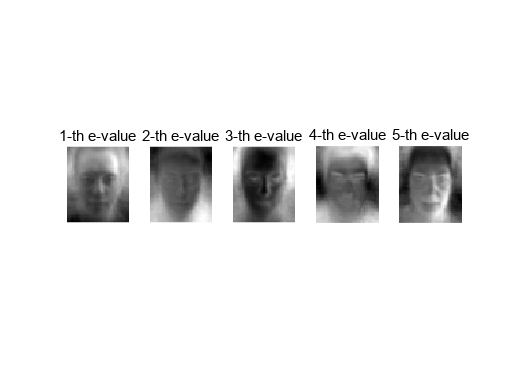

%visualize top 5 eigenfaces
figure
for i=1:5
    temp = coeff(:,i);
    temp = reshape(temp,[56,46]);
    txt = sprintf("%d-th e-value",i);
    subplot(1,5,i); imshow(temp,[]); title(txt,'FontSize',9);
end
saveas(gcf,'images/top5_eface_1.png');

% Reconstruction error - differing #.of eigfaces

n_eigvecs = 150;        %n : top-N eigfaces to use
reconstructed = score(:,1:n_eigvecs) * coeff(:,1:n_eigvecs)' + repmat(mu, train_size, 1);
%tmp = coeff(:,1:n_eigvecs); reconstructed = (tmp*tmp'*A')' + repmat(mu, train_size, 1);
reconst_error = norm(reconstructed-X_train);
%results("N-eigvecs") = n_eigvecs; results("reconst-error") = reconst_error;
results.n_eigvecs = n_eigvecs; results.reconst_error = reconst_error;

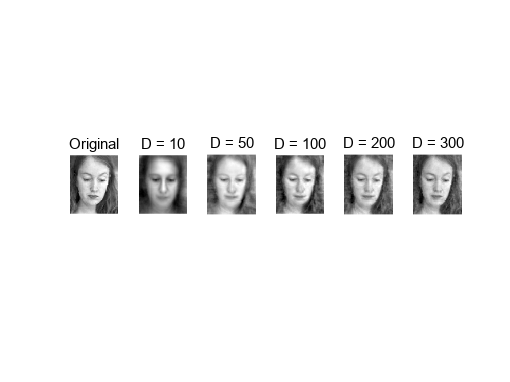

% Reconstruction error & Visualization - differing #.of eigfaces
list_n = [10,50,100,200,300];
reconst_err_list = [];
figure
tmp_img = X_train(15,:); tmp_img = reshape(tmp_img,[56,46]);
subplot(1,6,1); imshow(tmp_img,[]); title('Original','FontSize',9);
for i=1:5
    %tmp = coeff(:,1:list_n(i)); reconstructed = (tmp*tmp'*A')' + repmat(mu, train_size, 1);
    reconstructed = score(:,1:list_n(i)) * coeff(:,1:list_n(i))' + repmat(mu, train_size, 1);
    reconst_err_list = [reconst_err_list, norm(reconstructed-X_train)];
    tmp_img = reconstructed(15,:); tmp_img = reshape(tmp_img,[56,46]);
    txt = sprintf("D = %d",list_n(i));
    subplot(1,6,i+1); imshow(tmp_img,[]); title(txt,'FontSize',9);
end
saveas(gcf,'images/reconst_1.png');

% Classifier

X_train_T = X_train * coeff(:,1:n_eigvecs);  %reduced to N-dimensions
X_test_T = X_test * coeff(:,1:n_eigvecs);

%fitting KNN-Classifier
tic
Mbl = fitcknn(X_train_T,y_train,'NumNeighbors',1);
cls_train_time = toc;
%results("cls-train-time") = cls_train_time;
results.cls_train_time = cls_train_time;

%running on test-set
pred = predict(Mbl,X_test_T);

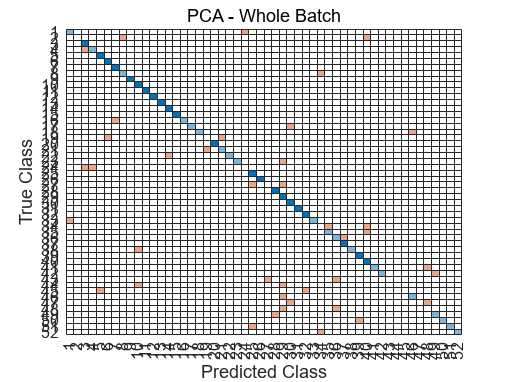

% Evaluation

%Confusion-matrix, visualization
confmat = confusionmat(y_test,pred);
figure
confchart = confusionchart(confmat);
confchart.Title = 'PCA - Whole Batch';
confchart.XLabel = 'Predicted Class';
confchart.YLabel = 'True Class';
saveas(gcf,'images/confmat_1.png');


%eval metrics - micro
stats = statsOfMeasure(confmat,0);
acc = stats.microAVG(8);
f1 = stats.microAVG(9);
%results("accuracy") = acc; results("micro-F1") = f1;
results.accuracy = acc; results.f1 = f1;
%results

# PCA : (Fast) Whole batch

% Performing PCA - all eigenvectors
results_fast = struct;

tic
%[coeff,score,~,~,~,mu] = pca(X_train);
[coeff,~,mu,A,~] = pca_fast(X_train);
pca_time = toc;
train_size = size(X_train,1);

results_fast.pca_time = pca_time;

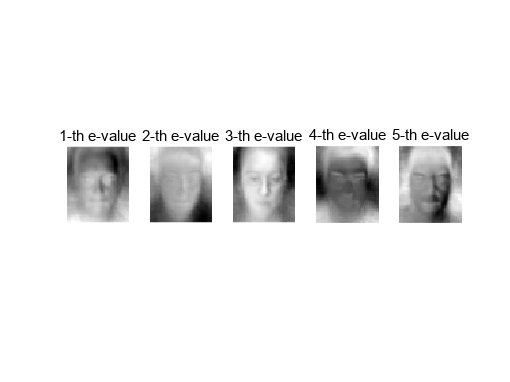

%visualize top 5 eigenfaces
figure
for i=1:5
    temp = coeff(:,i);
    temp = reshape(temp,[56,46]);
    txt = sprintf("%d-th e-value",i);
    subplot(1,5,i); imshow(temp,[]); title(txt,'FontSize',9);
end
saveas(gcf,'images/top5_eface_2.png');

% Reconstruction errors - differing #.of eigfaces
list_n = [10,50,100,200,300];
reconst_err_list = [];
for i=1:5
    tmp = coeff(:,1:list_n(i)); 
    reconstructed = (tmp*tmp'*A')' + repmat(mu, train_size, 1);
    reconst_err_list = [reconst_err_list, norm(reconstructed-X_train)];
end

results_fast.reconst_err_x = list_n;
results_fast.reconst_err_y = reconst_err_list;

n_eigvecs = 150;        %n : top-N eigfaces to use
results_fast.n_eigvecs = n_eigvecs;

% Classifier

X_train_T = X_train * coeff(:,1:n_eigvecs);  %reduced to N-dimensions
X_test_T = X_test * coeff(:,1:n_eigvecs);

%fitting KNN-Classifier
tic
Mbl = fitcknn(X_train_T,y_train,'NumNeighbors',1);
cls_train_time = toc;
results_fast.cls_train_time = cls_train_time;

%running on test-set
pred = predict(Mbl,X_test_T);

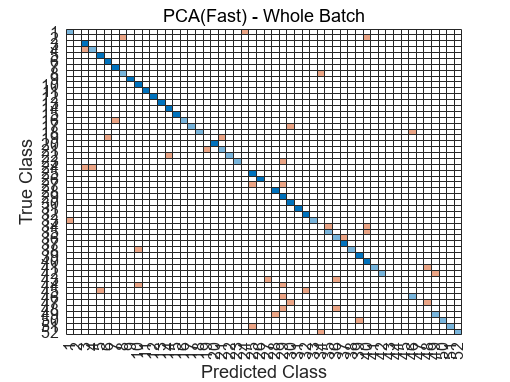

% Evaluation

%Confusion-matrix, visualization
confmat = confusionmat(y_test,pred);
figure
confchart = confusionchart(confmat);
confchart.Title = 'PCA(Fast) - Whole Batch';
confchart.XLabel = 'Predicted Class';
confchart.YLabel = 'True Class';
saveas(gcf,'images/confmat_2.png');

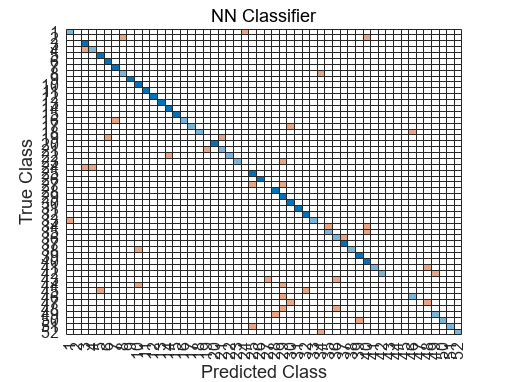


figure
confchart = confusionchart(confmat);
confchart.Title = 'NN Classifier';
confchart.XLabel = 'Predicted Class';
confchart.YLabel = 'True Class';
saveas(gcf,'results/confmat_nn.png');


%eval metrics - micro
stats = statsOfMeasure(confmat,0);
acc = stats.microAVG(8);
f1 = stats.microAVG(9);
results_fast.accuracy = acc; results_fast.f1 = f1;
%results_fast

# PCA : 1st-batch-only

% Performing PCA - all eigenvectors
results_1batch = struct;

tic
%[coeff,score,~,~,~,mu] = pca(X_train_1);
[coeff,~,mu,A,~] = pca_fast(X_train_1);
pca_time = toc;
train_size = size(X_train_1,1);
results_1batch.pca_time = pca_time;

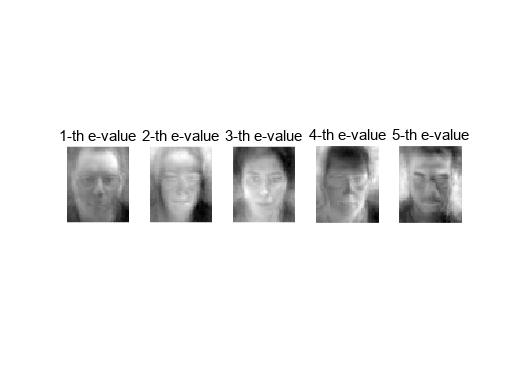

%visualize top 5 eigenfaces
figure
for i=1:5
    temp = coeff(:,i);
    temp = reshape(temp,[56,46]);
    txt = sprintf("%d-th e-value",i);
    subplot(1,5,i); imshow(temp,[]); title(txt,'FontSize',9);
end
saveas(gcf,'images/top5_eface_3.png');

% Reconstruction errors - differing #.of eigfaces
list_n = [10,50,100];
reconst_err_list = [];
for i=1:3
    tmp = coeff(:,1:list_n(i)); 
    reconstructed = (tmp*tmp'*A')' + repmat(mu, train_size, 1);
    reconst_err_list = [reconst_err_list, norm(reconstructed-X_train_1)];
end

results_1batch.reconst_err_x = list_n;
results_1batch.reconst_err_y = reconst_err_list;

n_eigvecs = 50;        %n : top-N eigfaces to use
results_1batch.n_eigvecs = n_eigvecs;

% Classifier

X_train_T = X_train_1 * coeff(:,1:n_eigvecs);  %reduced to N-dimensions
X_test_T = X_test * coeff(:,1:n_eigvecs);

%fitting KNN-Classifier
tic
Mbl = fitcknn(X_train_T,y_train_1,'NumNeighbors',1);
cls_train_time = toc;
results_1batch.cls_train_time = cls_train_time;

%running on test-set
pred = predict(Mbl,X_test_T);

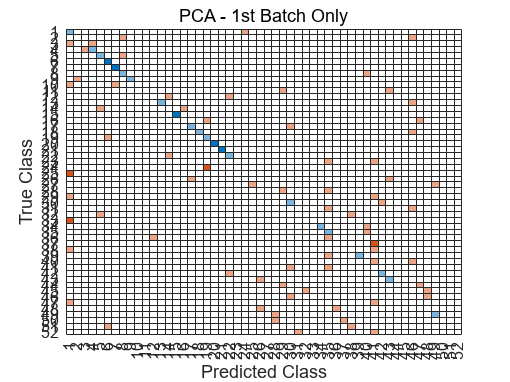

% Evaluation

%Confusion-matrix, visualization
confmat = confusionmat(y_test,pred);
figure
confchart = confusionchart(confmat);
confchart.Title = 'PCA - 1st Batch Only';
confchart.XLabel = 'Predicted Class';
confchart.YLabel = 'True Class';
saveas(gcf,'images/confmat_3.png');


%eval metrics - micro
stats = statsOfMeasure(confmat,0);
acc = stats.microAVG(8);
f1 = stats.microAVG(9);
results_1batch.accuracy = acc; results_1batch.f1 = f1;
%results_1batch

# Incremental PCA

% Incremental PCA : 4 training subsets
results_incremental = struct;
n_eigvecs = 50;

n1 = size(X_train_1,1);
n2 = size(X_train_2,1);
n3 = size(X_train_3,1);
n4 = size(X_train_4,1);

tic
[coeff_1,~,mu_1,A1,~] = pca_fast(X_train_1);
[coeff_2,~,mu_2,A2,~] = pca_fast(X_train_2);
[coeff_3,~,mu_3,A3,~] = pca_fast(X_train_3);
[coeff_4,~,mu_4,A4,~] = pca_fast(X_train_4);

%inc-PCA
n12 = n1+n2; mu_12 = (mu_1*n2+mu_2*n2)/n12; diff = mu_1-mu_2; 
s1 = (A1'*A1)./n1; s2 = (A2'*A2)./n2; 
s12 = (n1/n12).*s1 + (n2/n12).*s2 + ((n1*n2)/n12).*(diff'*diff);
pi = gson([coeff_1(:,1:n_eigvecs),coeff_2(:,1:n_eigvecs),diff']);
S12 = pi'*s12*pi;
[R,~] = eig(S12); coeff_12 = pi*R;

%inc-PCA
n123 = n12+n3; mu_123 = (mu_12*n12+mu_3*n3)/n123; diff = mu_12-mu_3;
s3 = (A3'*A3)./n3; 
s123 = (n12/n123).*s12 + (n3/n123).*s3 + ((n12*n3)/n123).*(diff'*diff);
pi = gson([coeff_12(:,1:n_eigvecs*2),coeff_3(:,1:n_eigvecs),diff']);
S123 = pi'*s123*pi;
[R,~] = eig(S123); coeff_123 = pi*R;

%inc-PCA
n1234 = n123+n4; mu_1234 = (mu_123*n123+mu_4*n4)/n1234; diff = mu_123-mu_4;
s4 = (A4'*A4)./n4; 
s1234 = (n123/n1234).*s123 + (n4/n1234).*s4 + ((n123*n4)/n1234).*(diff'*diff);
pi = gson([coeff_123(:,1:n_eigvecs*3),coeff_4(:,1:n_eigvecs),diff']);
S1234 = pi'*s1234*pi;
[R,D] = eig(S1234); coeff_1234 = pi*R;

%time.
pca_time = toc;
results_incremental.pca_time = pca_time;

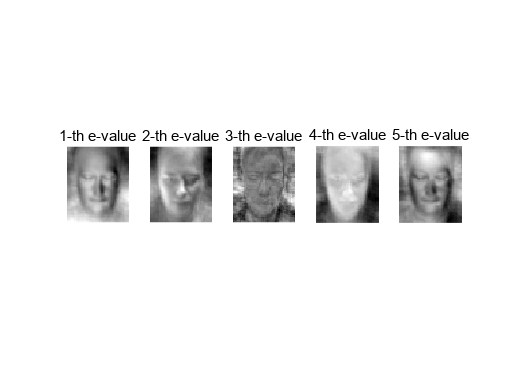

%visualize top 5 eigenfaces
figure
for i=1:5
    temp = coeff_1234(:,i);
    temp = reshape(temp,[56,46]);
    txt = sprintf("%d-th e-value",i);
    subplot(1,5,i); imshow(temp,[]); title(txt,'FontSize',9);
end
saveas(gcf,'images/top5_eface_4.png');

% Reconstruction errors - differing #.of eigfaces
X_train_1234 = [X_train_1;X_train_2;X_train_3;X_train_4];
train_size = size(X_train_1234,1);
A1234 = X_train_1234 - repmat(mu_1234,train_size,1);

list_n = [10,50,100,200];
reconst_err_list = [];
for i=1:4
    tmp = coeff_1234(:,1:list_n(i)); 
    reconstructed = (tmp*tmp'*A1234')' + repmat(mu_1234, train_size, 1);
    reconst_err_list = [reconst_err_list, norm(reconstructed-X_train_1234)];
end

results_incremental.reconst_err_x = list_n;
results_incremental.reconst_err_y = reconst_err_list;

n_eigvecs = 150;        %n : top-N eigfaces to use
results_incremental.n_eigvecs = n_eigvecs;

% Classifier

X_train_T = X_train * coeff_1234(:,1:n_eigvecs);  %reduced to N-dimensions
X_test_T = X_test * coeff_1234(:,1:n_eigvecs);

%fitting KNN-Classifier
tic
Mbl = fitcknn(X_train_T,y_train,'NumNeighbors',1);
cls_train_time = toc;
results_incremental.cls_train_time = cls_train_time;

%running on test-set
pred = predict(Mbl,X_test_T);

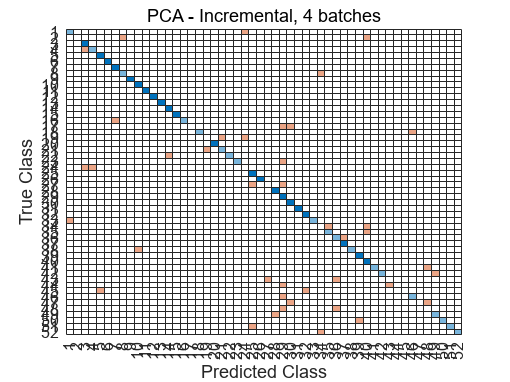

% Evaluation

%Confusion-matrix, visualization
confmat = confusionmat(y_test,pred);
figure
confchart = confusionchart(confmat);
confchart.Title = 'PCA - Incremental, 4 batches';
confchart.XLabel = 'Predicted Class';
confchart.YLabel = 'True Class';
saveas(gcf,'images/confmat_4.png');


%eval metrics - micro
stats = statsOfMeasure(confmat,0);
acc = stats.microAVG(8);
f1 = stats.microAVG(9);
results_incremental.accuracy = acc; results_incremental.f1 = f1;
%results_incremental

# Incremental PCA - FAST/simple

% Incremental PCA : 4 training subsets
results_incremental_simple = struct;
n_eigvecs = 50;

n1 = size(X_train_1,1);
n2 = size(X_train_2,1);
n3 = size(X_train_3,1);
n4 = size(X_train_4,1);

tic
%Subset 1.
[coeff_1,~,mu_1,A1,~] = pca_fast(X_train_1);

%Subset 2.
%inc-PCA(fast)
[coeff_12,~,mu_12,A12,~] = pca_fast([X_train_1;X_train_2]);

%Subset 3.
%inc-PCA(fast)
[coeff_123,~,mu_123,A123,~] = pca_fast([X_train_1;X_train_2;X_train_3]);

%Subset 4.
%inc-PCA(fast)
[coeff_1234,~,mu_1234,A1234,~] = pca_fast([X_train_1;X_train_2;X_train_3;X_train_4]);

%time.
pca_time = toc;
results_incremental_simple.pca_time = pca_time;

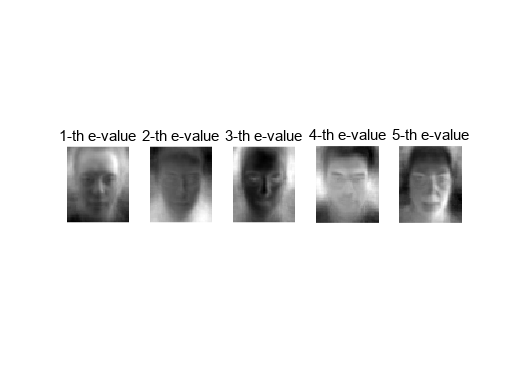

%visualize top 5 eigenfaces
figure
for i=1:5
    temp = coeff_1234(:,i);
    temp = reshape(temp,[56,46]);
    txt = sprintf("%d-th e-value",i);
    subplot(1,5,i); imshow(temp,[]); title(txt,'FontSize',9);
end
saveas(gcf,'images/top5_eface_5.png');

% Reconstruction errors - differing #.of eigfaces
X_train_1234 = [X_train_1;X_train_2;X_train_3;X_train_4];
train_size = size(X_train_1234,1);

list_n = [10,50,100,200];
reconst_err_list = [];
for i=1:4
    tmp = coeff_1234(:,1:list_n(i)); 
    reconstructed = (tmp*tmp'*A1234')' + repmat(mu_1234, train_size, 1);
    reconst_err_list = [reconst_err_list, norm(reconstructed-X_train_1234)];
end

results_incremental_simple.reconst_err_x = list_n;
results_incremental_simple.reconst_err_y = reconst_err_list;

n_eigvecs = 150;        %n : top-N eigfaces to use
results_incremental_simple.n_eigvecs = n_eigvecs;


% Classifier

X_train_T = X_train * coeff_1234(:,1:n_eigvecs);  %reduced to N-dimensions
X_test_T = X_test * coeff_1234(:,1:n_eigvecs);

%fitting KNN-Classifier
tic
Mbl = fitcknn(X_train_T,y_train,'NumNeighbors',1);
cls_train_time = toc;
results_incremental_simple.cls_train_time = cls_train_time;

%running on test-set
pred = predict(Mbl,X_test_T);

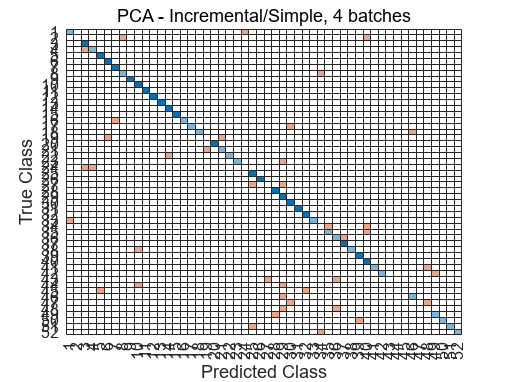

% Evaluation

%Confusion-matrix, visualization
confmat = confusionmat(y_test,pred);
figure
confchart = confusionchart(confmat);
confchart.Title = 'PCA - Incremental/Simple, 4 batches';
confchart.XLabel = 'Predicted Class';
confchart.YLabel = 'True Class';
saveas(gcf,'images/confmat_5.png');


%eval metrics - micro
stats = statsOfMeasure(confmat,0);
acc = stats.microAVG(8);
f1 = stats.microAVG(9);
results_incremental_simple.accuracy = acc; 
results_incremental_simple.f1 = f1;
%results_incremental

# Results

% RESULTS
results

results = 다음 필드를 포함한 struct :
          pca_time: 0.0878
         n_eigvecs: 150
     reconst_error: 848.2335
    cls_train_time: 0.0383
          accuracy: 0.6154
                f1: 0.6154


results_fast

results_fast = 다음 필드를 포함한 struct :
          pca_time: 0.0319
     reconst_err_x: [10 50 100 200 300]
     reconst_err_y: [5.0255e+03 1.9063e+03 1.1535e+03 655.2540 416.4382]
         n_eigvecs: 150
    cls_train_time: 0.0720
          accuracy: 0.6154
                f1: 0.6154


results_1batch

results_1batch = 다음 필드를 포함한 struct :
          pca_time: 0.0105
     reconst_err_x: [10 50 100]
     reconst_err_y: [2.7078e+03 997.3994 456.0337]
         n_eigvecs: 50
    cls_train_time: 0.0109
          accuracy: 0.2596
                f1: 0.2596


results_incremental

results_incremental = 다음 필드를 포함한 struct :
          pca_time: 0.3241
     reconst_err_x: [10 50 100 200]
     reconst_err_y: [6.0016e+03 1.9540e+03 1.2009e+03 1.0142e+03]
         n_eigvecs: 150
    cls_train_time: 0.0072
          accuracy: 0.6058
                f1: 0.6058


results_incremental_simple

results_incremental_simple = 다음 필드를 포함한 struct :
          pca_time: 0.0776
     reconst_err_x: [10 50 100 200]
     reconst_err_y: [5.0255e+03 1.9063e+03 1.1535e+03 655.2540]
         n_eigvecs: 150
    cls_train_time: 0.0084
          accuracy: 0.6154
                f1: 0.6154


save("results/p2_results.mat",'results','results_fast','results_1batch','results_incremental','results_incremental_simple');